# Proof of Concept for ME5714 final

## Finding derivative in frequency domain

% --Setup
    clear; clc; format compact; close all;

% --Making initial Signal
    sample_freq = 2048;
    f = 1;                      % Frequency (hz)
    w = f*2*pi;                 % Frequency (rad/s)
    amplitude = 1;              % Amplitude
    T = 20;                     % Period of signal (s)
    t = 0:1/sample_freq:T;
    wave = amplitude*sin(w*t);
    N = length(wave);
    
% --Plot solution
    figure(1)
    plot(t,wave);
        hold on
        grid on
        xlabel('Time (s)')
        ylabel('Amplitude')
        title('Time Domain of Signal')
        
% --FFT of signal
    fourier = fft(wave);
    magnitude = abs(fourier);
    amplitude = 2*magnitude ./ (length(wave));
    
% --Define Frequency
    frequency = (1/T)*(-N/2:(N/2)-1);
    frequency = fftshift(frequency)

frequency = 	1.0e+03 *

    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0014    0.0015    0.0015    0.0016    0.0016    0.0017    0.0017    0.0018    0.0018    0.0019    0.0019    0.0020    0.0020    0.0021    0.0021    0.0022    0.0022    0.0023    0.0023    0.0024    0.0024    0.0025


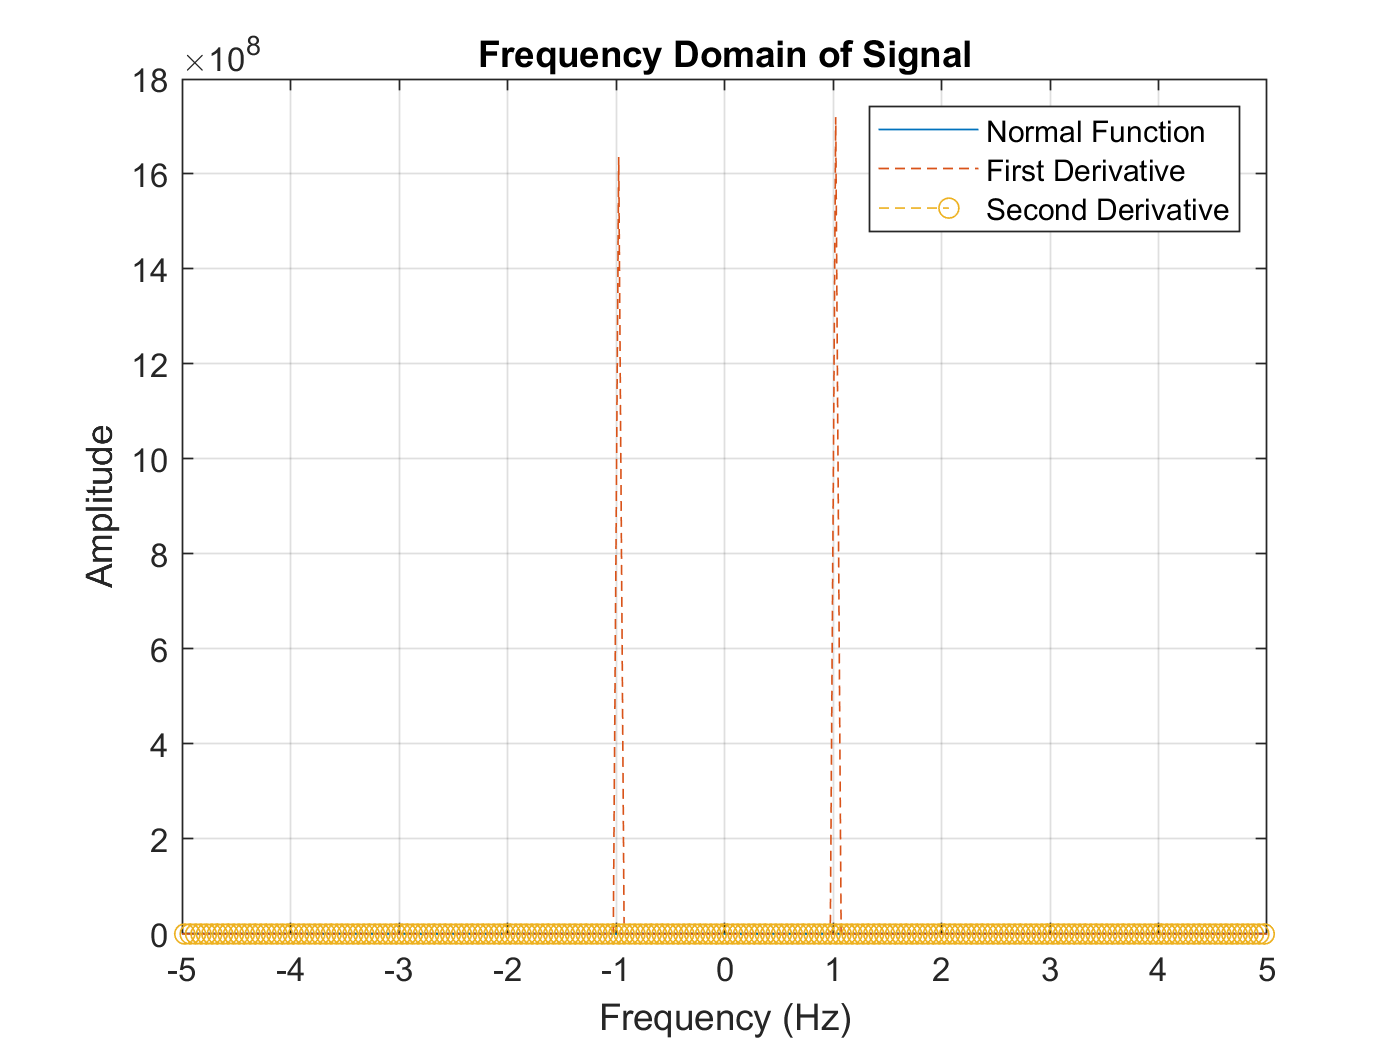

    
% --Plot FFT
    figure(2)
    plot(frequency,amplitude)
        hold on
        grid on
        xlabel('Frequency (Hz)')
        ylabel('Amplitude')
        xlim([-5 5])
        
% --Taking derivative
    df = 1i * frequency .* fourier;
    df_abs = abs(df);
    df_amp = (2*df_abs) .* length(wave);
    
    figure(2)
    plot(frequency,df_amp,'--')
        title('Frequency Domain of Signal');

% --Taking second derivative
    ddf = 1i * frequency .* df;
    ddf_abs = abs(ddf);
    ddf_amp = (2*ddf_abs) ./ (length(wave));
    
    figure(2)
    stem(frequency, ddf_amp,'--')
        legend('Normal Function','First Derivative','Second Derivative');

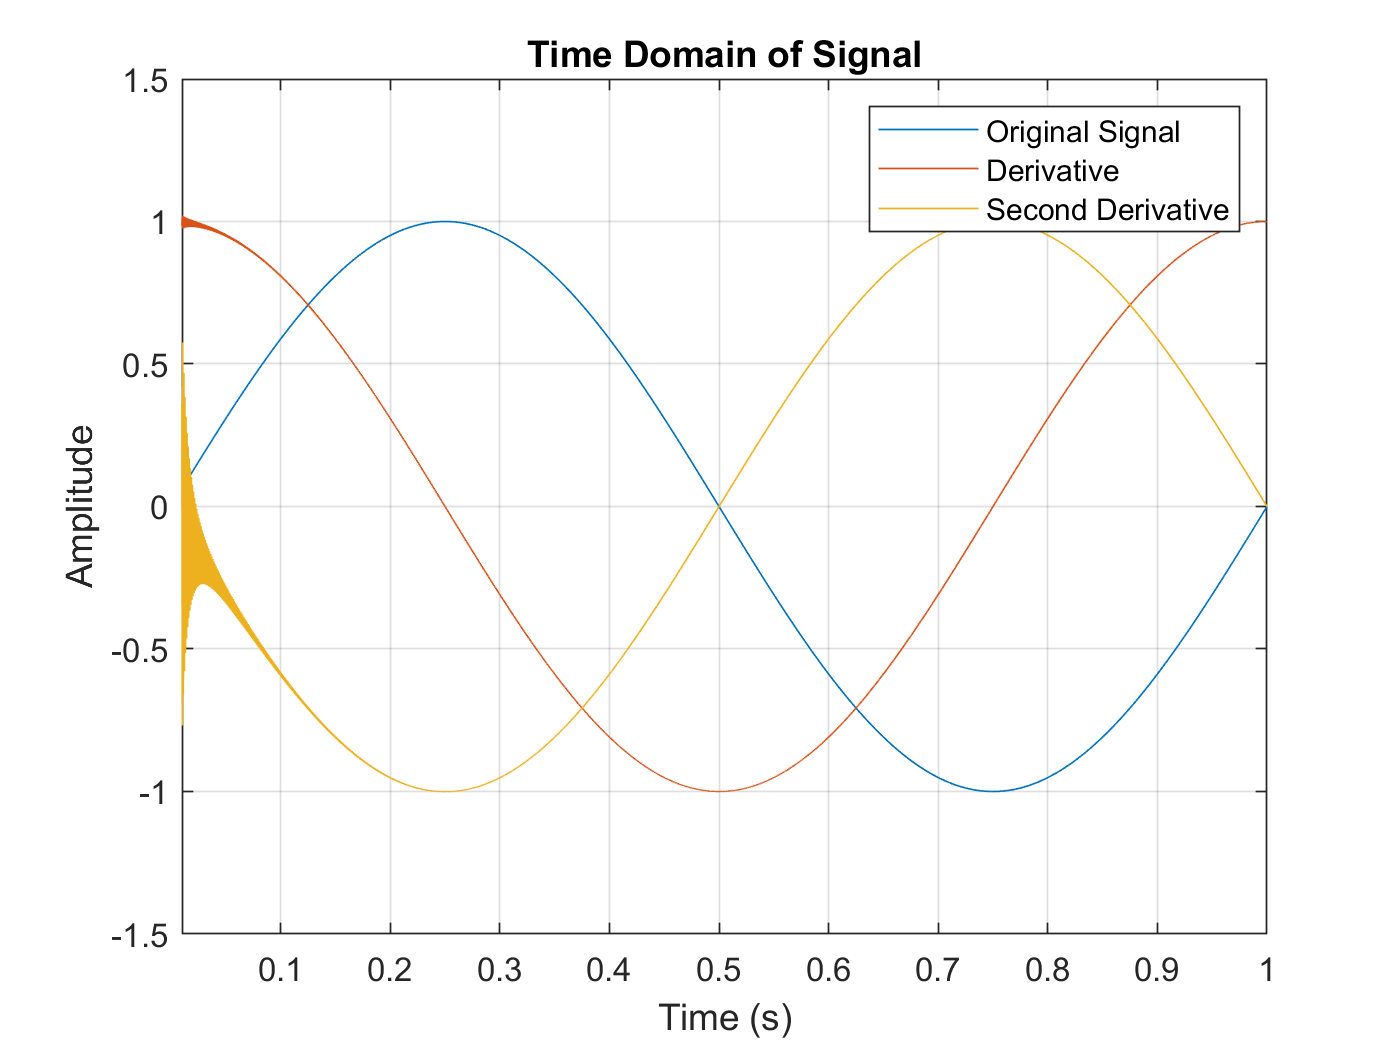


% --Inverse FFT
    dt = real(ifft(df));
    ddt = real(ifft(ddf));
    
% --Plot derivative
    figure(1)
    plot(t,dt)
    plot(t,ddt)
        legend('Original Signal', 'Derivative','Second Derivative')
        xlim([0.01 1])

## Modulating and Demodulating a signal

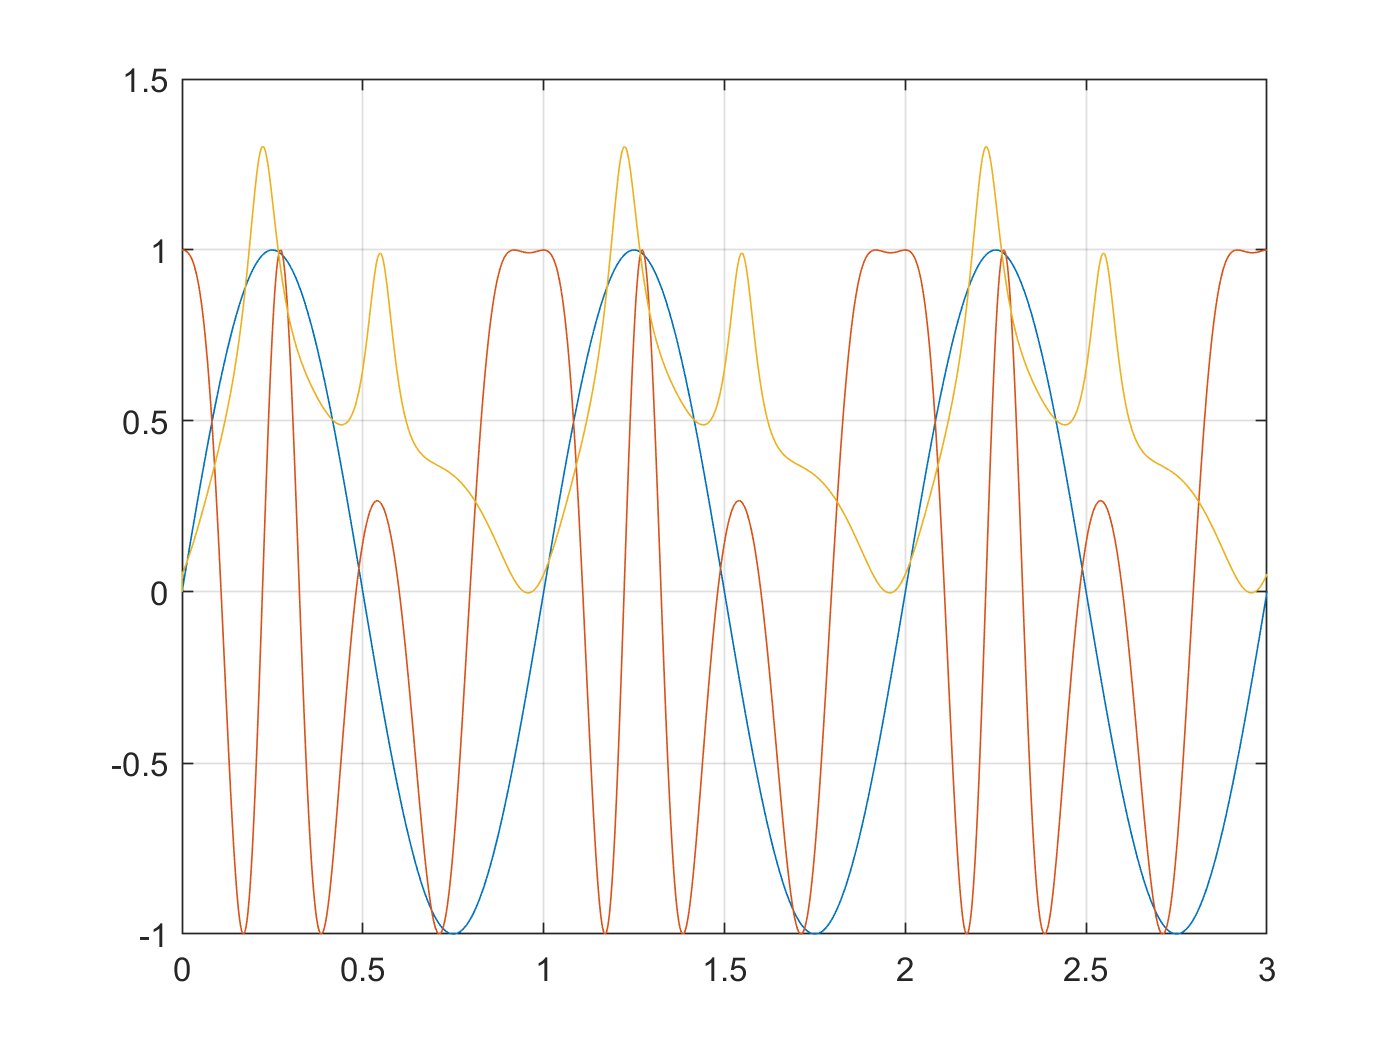

% --Modulate wave
    wave_modulated = fmmod(wave,1,2048, 4);
    
% --Plot both
    figure()
    plot(t,wave)
        hold on
    plot(t,wave_modulated)
        grid on
        xlim([0 3])
        
% --Using FM demod
    wave_demodulated = fmdemod(wave_modulated,1,2048,4);
    plot(t,wave_demodulated)